# Junctional Medial Intensity Measurements

## Import necessary files

corePath = '/Volumes/martin/users/cao929/';%Define the shared path for your files on a pc
workingFolder = 'Wilson/';%Define the shared path for your files on a pc
imName = "S35 3.09"; %Specify the name of the file of interest      

actinPath = strcat(corePath, workingFolder, 'Projections/', imName, '_F-Actin_Projection.tif'); %Define the path to the actin projection
myosinPath = strcat(corePath, workingFolder, 'Projections/', imName, '_Myosin IIB_Projection.tif'); %Define the path to the myosin projection
segmentPath = strcat(corePath, workingFolder, 'Segmentation Masks/', imName, '_Myosin IIB_MaxProjection_cp_masks.png'); % Define the path to the Segmentation mask
outlinePath = strcat(corePath, workingFolder, 'Outlines/', imName, '_Myosin IIB_MaxProjection_cp_outlines.txt'); %Define the path to the outline
figOutPutDirectory = strcat(corePath, workingFolder, 'Figures/', imName); %Define the path where figures will be saved


originalAct = imread(actinPath);
originalMyo = imread(myosinPath);
segmentation = double(imread(segmentPath));
outlines = importdata(outlinePath);

## Prepare outlines for junctional vs medial comparison

rowOutline = reshape(outlines',2, []); %convert the outline matrix into a 2 row matrix so that coordinates listed as y,x
rowOutline = rowOutline'; %switch row matrix to be two columns
noNan = rowOutline(~isnan(rowOutline))+1; %Pull out all values that are not NaN, adjust index from 0 to 1
noNan = reshape(noNan, [], 2); %reshape from single column back to two columns

junctions = ones(size(originalAct)); %create a 2048x2048 matrix of just ones as a base image
for i = 1:length(noNan)
    junctions(noNan(i,2),noNan(i,1)) = 0; %for each coordinate pair, reassign the one to be zero to "remove" areas of junction from the image"
end

disc = strel('disk',5); %creates a disk structural element of radius five
thickJxns = imerode(junctions, disc); %use the disk to increase the thickness of the junctions

### Optional: Show the images and the segmenations

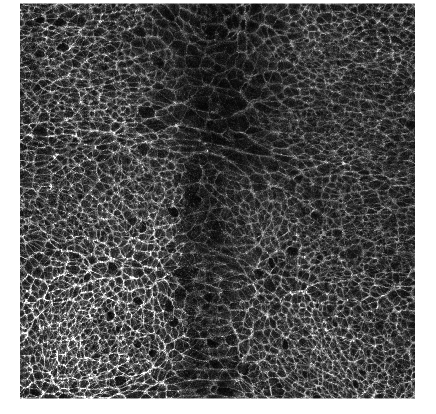

figure
imshow(originalMyo)

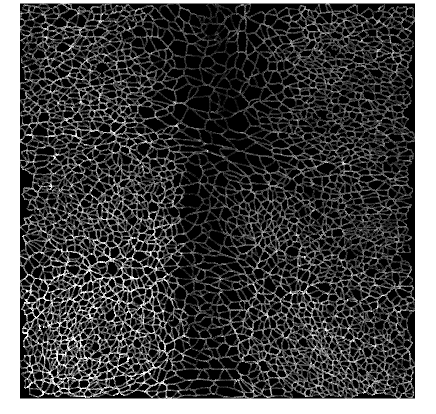

figure
justJxn = double(originalMyo).*~thickJxns;
imshow(uint8(justJxn))

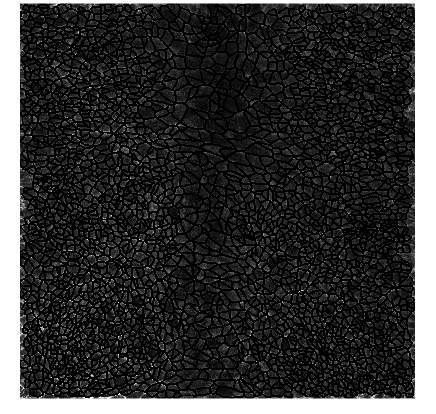

figure
justMed = double(originalMyo).*thickJxns;
imshow(uint8(justMed))

## Pull out Whole Cell Intensity Data using the segmentation

measMyo = regionprops(segmentation, originalMyo, "Area", "Centroid", ...
    "PixelValues", "Orientation", "MajorAxisLength", "MinorAxisLength"); %Pull out area, center, and all pixel intensities for each region
measAct = regionprops(segmentation, originalAct, "PixelValues"); %Pull out pixel intensities. Only need area and center from one image because they are shared
centers = measMyo.Centroid; %Pull out the coordinates for the centers of each cell
yPos = centers(2:2:end)'; %Create a vector of y-positions
xPos = centers(1:2:end)'; %Create a vector of x-positions

resolution = 2.4089*2.4089; %Define the pixels^2/µm^2 resolution
area = [measMyo.Area]'/resolution; %convert pixel areas to µm
avgArea = mean(area); %Calculate the average area
normArea = (area - avgArea)/avgArea; %Calculate the normalized area

%Create two empty vectors of the same length as the number of cells in the image
totIntMyo = zeros(length(measMyo),1); 
avgIntMyo = zeros(length(measMyo),1);
%For each cell calculate the total (sum) intenstity and average intensity of myosin and save into the relevant vecors
for i = 1:length(measMyo) 
    totIntMyo(i) = sum(measMyo(i).PixelValues);
    avgIntMyo(i) = mean(measMyo(i).PixelValues);
end
avgCellMyo = mean(totIntMyo); %Find the average total intensity across all cells
avgAvgMyo = mean(avgIntMyo); %Find the average average intensity across all cells
normMyo = (totIntMyo - avgCellMyo)/avgCellMyo; %Calculate the normalized total intensity
normAvgMyo = (avgIntMyo - avgAvgMyo)/avgAvgMyo; %Calculate the normalized average total intensity

%Do the same thing as above but for Actin 
totIntAct = zeros(length(measAct),1);
avgIntAct = zeros(length(measAct),1);
for i = 1:length(measMyo)
    totIntAct(i) = sum(measAct(i).PixelValues);
    avgIntAct(i) = mean(measAct(i).PixelValues);
end
avgCellAct = mean(totIntAct);
avgAvgAct = mean(avgIntAct);
normAct = (totIntAct - avgCellAct)/avgCellAct;
normAvgAct = (avgIntAct - avgAvgAct)/avgAvgAct;

## Calculate medial and junctional intensities

medSegmentation = segmentation.*thickJxns; %remove the junctional section from all of the cells
medMyo = regionprops(medSegmentation, originalMyo, "Area", "PixelValues"); %Pull pixel intensities for medial pool of myosin
medAct = regionprops(medSegmentation, originalAct, "PixelValues"); %Pull pixel intensitiesfor medial pool of actin

jxnSegmentation = segmentation.*~thickJxns; %remove the medial region of all the cells
jxnMyo = regionprops(jxnSegmentation, originalMyo, "Area", "PixelValues"); %Pull pixel intensities for junctional pool of myosin
jxnAct = regionprops(jxnSegmentation, originalAct, "PixelValues"); %Pull pixel intensitiesfor junctional pool of actin

%Calculate the areas of the medial and junctional pools in µm
medArea = [medMyo.Area]'/resolution; 
avgMedArea = mean(medArea);
jxnArea = [jxnMyo.Area]'/resolution;
avgJxnArea = mean(jxnArea);

%Measure the total and average intensities for both the junctional and medial myosin pools
totMedMyo = zeros(length(medMyo),1);
avgMedMyo = zeros(length(medMyo),1);
totJxnMyo = zeros(length(jxnMyo),1);
avgJxnMyo = zeros(length(jxnMyo),1);
for i = 1:length(measMyo)
    totMedMyo(i) = sum(medMyo(i).PixelValues);
    avgMedMyo(i) = mean(medMyo(i).PixelValues);
    totJxnMyo(i) = sum(jxnMyo(i).PixelValues);
    avgJxnMyo(i) = mean(jxnMyo(i).PixelValues);
end
%Calculate the average for both the total/average intensities in junctional and medial pools of myosin
avgTotMedMyo = mean(totMedMyo);
avgTotJxnMyo = mean(totJxnMyo);
avgAvgMedMyo = mean(avgMedMyo(~isnan(avgMedMyo)));
avgAvgJxnMyo = mean(avgJxnMyo(~isnan(avgJxnMyo)));
%Normalize the above measurements for Myosin
normMedMyo = (totMedMyo - avgTotMedMyo)/avgTotMedMyo;
normJxnMyo = (totJxnMyo - avgTotJxnMyo)/avgTotJxnMyo;
normAvgMedMyo = (avgMedMyo - avgAvgMedMyo)/avgAvgMedMyo;
normAvgJxnMyo = (avgJxnMyo - avgAvgJxnMyo)/avgAvgJxnMyo;

%Do the same thing as above but for Actin
totMedAct = zeros(length(medAct),1);
avgMedAct = zeros(length(medAct),1);
totJxnAct = zeros(length(jxnAct),1);
avgJxnAct = zeros(length(jxnAct),1);
for i = 1:length(measMyo)
    totMedAct(i) = sum(medAct(i).PixelValues);
    avgMedAct(i) = mean(medAct(i).PixelValues);
    totJxnAct(i) = sum(jxnAct(i).PixelValues);
    avgJxnAct(i) = mean(jxnAct(i).PixelValues);
end
avgTotMedAct = mean(totMedAct);
avgTotJxnAct = mean(totJxnAct);
avgAvgMedAct = mean(avgMedAct(~isnan(avgMedAct)));
avgAvgJxnAct = mean(avgJxnAct(~isnan(avgJxnAct)));
normMedAct = (totMedAct - avgTotMedAct)/avgTotMedAct;
normJxnAct = (totJxnAct - avgTotJxnAct)/avgTotJxnAct;
normAvgMedAct = (avgMedAct - avgAvgMedAct)/avgAvgMedAct;
normAvgJxnAct = (avgJxnAct - avgAvgJxnAct)/avgAvgJxnAct;

## Create data table and sort 

%Create a table of all the calculate values to allow for pairing and sorting of data
measTable = table(area, normArea, yPos, xPos, totIntAct, avgIntAct, normAct, normAvgAct, ...
    totMedAct, avgMedAct, normMedAct, normAvgMedAct, ...
    totJxnAct, avgJxnAct, normJxnAct, normAvgJxnAct, ...
    totIntMyo, avgIntMyo, normMyo, normAvgMyo, ...
    totMedMyo, avgMedMyo, normMedMyo, normAvgMedMyo, ...
    totJxnMyo, avgJxnMyo, normJxnMyo, normAvgJxnMyo);

Error using table
All table variables must have the same number of rows.

## Define diverging color maps

%Define the RGB codes for several color maps that will be used below
divPWG = [0,68,27; 27,120,55; 90,174,97; 166,219,160; 217,240,211; 247,247,247; 231,212,232; 194,165,207; 153,112,171; 118,42,131; 64,0,75;]/255;
divRWB =[103,0,31; 178,24,43; 214,96,77; 244,165,130; 253,219,199; 247,247,247; 209,229,240; 146,197,222; 67,147,195; 33,102,172; 5,48,97;]/255;
divPiWG = [ 39,100,25; 77,146,33; 127,188,65; 184,225,134; 230,245,208; 247,247,247; 253,224,239; 241,182,218; 222,119,174; 197,27,125; 142,1,82;]/255;

## Plot Normalized Area

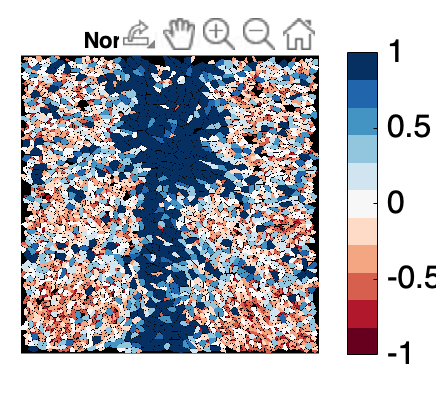

figure
segVis(segmentation, junctions, measTable.normArea, divRWB, 'k', 16, [-1, 1], "Normalized Area") %request to make an plot visualizing the segmentation
newOutPutDirectory = strcat(figOutPutDirectory, '_NormArea.png'); %Give your plot a descriptive name
exportgraphics(gcf, newOutPutDirectory,'Resolution', 600);